# Panel models with no cross section linkages

Tutorial file for testing panel models

## Housekeeping

clear
close all
clear classes

rehash path


import separable.*  


## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

medianFunc = @(x) median(x, 2);

flatFunc = @(x) x(:, :);

defaultColors = get(0, "defaultAxesColorOrder");


## Number of Samples

numPresampled = 100;

## Prepare meta information for the models

Note that the meta information is common to all panel BVAR models, regardless of the specific estimator used.

The properties are as follows:

**endogenousConcepts **–  a list of endogenous variables, listed without the country suffix. Plays the same role as **endogenousNames** in plain BVARs

**units **– a list of countries/units that share the same endogenous variables


estimStart = datex("1972-Q1");
estimEnd = datex("2014-Q4");
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousConcepts=["YER", "HICSA", "STN"], ...
    units=["US", "EA"], ...
    exogenous=["Oil"], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    identificationHorizon=12, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);



## Specifying and loading input data


inputTbl = tablex.fromFile("panelData.csv");
dataH = DataHolder(meta, inputTbl);

## Reduced form models

#### OLS Mean Group Panel

There is no estimator specific settings.

estimatorR1 = estimator.MeanOLSPanel(meta);

#### Bayesian Pooled Panel with Normal-Wishart priors

There is no estimator specific settings.

%estimatorR1 = estimator.NormalWishartPanel(meta);

#### Zellner- Hong Random Effect Panel

There is no estimator specific settings.

%estimatorR1 = estimator.ZellnerHongPanel(meta);

#### Hierarchical Panel

**S0 (0.001)** – The shape of the Inverse Gamma distribution of overal tightness

**V0 (0.001)** – The scale of the Inverse Gamma distribution of overal tightness

% estimatorR1 = estimator.HierarchicalPanel(meta);

### Creating the reduced form model


modelR1 = ReducedForm( ...
    meta=meta, ...
    dataHolder=dataH, ...
    estimator=estimatorR1 ...
);

## Estimation/sampling of the reduced form model 


modelR1.initialize();
info0 = modelR1.presample(numPresampled);


 Presampling from posterior (MeanOLSPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelR1.Presampled{1}.beta

ans =     1.0621
    0.0918
    0.0452
   -0.0857
   -0.2003
   -0.2871
   -0.3825
    0.3099
    0.1453
    0.1568


## Running Unconditional forecast 

### Settig up the forecast range and run the forecast

fcastStart = datex.shift(modelR1.Meta.EstimationEnd, -10); %The forecast starts 10 periods prior to the end of the estimation span.
fcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 0); %The forecast ends at the end of the estimation window.
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2012-Q2


fcastEnd = datetime
   2014-Q4



fcastTbx = modelR1.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx); %keeping only the pctiles set at the beginning of the file (10, 50, 90)



### Visualize the unconditional forecast

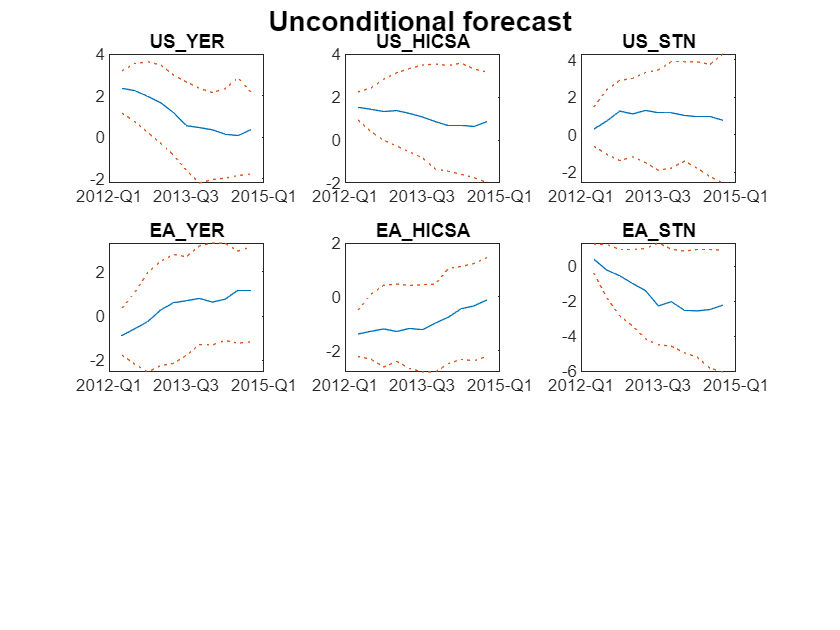


plotSettings = { ...
    {"color"}, {defaultColors(2,:); defaultColors(1,:); defaultColors(2,:)},  ...
    {"lineStyle"}, {":";"-";":"}, ...
};


ch = visual.Chartpack( ...
    span=datex.span(fcastStart, fcastEnd), ...
    namesToPlot=[modelR1.Meta.EndogenousNames], ...
    plotSettings=plotSettings ...
);

ch.Captions = "Unconditional forecast";
ch.plot(fcastPrctileTbx);

## Identification

### Cholesky

#### Seting up the identifier

identChol = identifier.Cholesky(order=[]);

modelS1 = Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();

info1 = modelS1.presample(numPresampled);


 Presampling from posterior (MeanOLSPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [42×1 double]
                 sigma: [3×3 double]
                  bhat: [42×1 double]
    IdentificationDraw: [1×1 struct]
                     D: [3×3×2 double]


#### Checking transition matrices

modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {12×1 cell}
        C: {12×1 cell}
    Sigma: [3×3×2 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans = ans(:,:,1) =

    1.0689   -0.0308    0.2238
    0.0829    0.9490    0.0758
    0.0894    0.0709    1.2292
   -0.1576    0.1271   -0.2093
   -0.0874   -0.0777    0.1020
   -0.2958   -0.1266   -0.4228
   -0.2907   -0.2067    0.0402
    0.3469    0.1542    0.0093
    0.0961   -0.0449    0.1892
    0.0695    0.1171    0.0304
   -0.1634   -0.1399   -0.0055
    0.0853    0.0817   -0.0270


ans(:,:,2) =

    1.0689   -0.0308    0.2238
    0.0829    0.9490    0.0758
    0.0894    0.0709    1.2292
   -0.1576    0.1271   -0.2093
   -0.0874   -0.0777    0.1020
   -0.2958   -0.1266   -0.4228
   -0.2907   -0.2067    0.0402
    0.3469    0.1542    0.0093
    0.0961   -0.0449    0.1892
    0.0695    0.1171    0.0304
   -0.1634   -0.1399   -0.0055
    0.0853    0.0817   -0.0270


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans = ans(:,:,1) =

    1.0689   -0.0308    0.2238
    0.0829    0.9490    0.0758
    0.0894    0.0709    1.2292
   -0.1576    0.1271   -0.2093
   -0.0874   -0.0777    0.1020
   -0.2958   -0.1266   -0.4228
   -0.2907   -0.2067    0.0402
    0.3469    0.1542    0.0093
    0.0961   -0.0449    0.1892
    0.0695    0.1171    0.0304
   -0.1634   -0.1399   -0.0055
    0.0853    0.0817   -0.0270


ans(:,:,2) =

    1.0689   -0.0308    0.2238
    0.0829    0.9490    0.0758
    0.0894    0.0709    1.2292
   -0.1576    0.1271   -0.2093
   -0.0874   -0.0777    0.1020
   -0.2958   -0.1266   -0.4228
   -0.2907   -0.2067    0.0402
    0.3469    0.1542    0.0093
    0.0961   -0.0449    0.1892
    0.0695    0.1171    0.0304
   -0.1634   -0.1399   -0.0055
    0.0853    0.0817   -0.0270


#### Checking scaling matrix

modelS1.Presampled{1}.D

ans = ans(:,:,1) =

    0.7501    0.2113    0.1842
         0    0.5079    0.0440
         0         0    0.7030


ans(:,:,2) =

    0.7501    0.2113    0.1842
         0    0.5079    0.0440
         0         0    0.7030


modelS1.Presampled{2}.D

ans = ans(:,:,1) =

    0.7501    0.2113    0.1842
         0    0.5079    0.0440
         0         0    0.7030


ans(:,:,2) =

    0.7501    0.2113    0.1842
         0    0.5079    0.0440
         0         0    0.7030


## Impulse respones (IRF)

### Plot settings

plotStart = datex.shift(modelS1.Meta.EstimationEnd, 1); 
plotEnd = datex.shift(modelS1.Meta.EstimationEnd, modelS1.Meta.IdentificationHorizon); 
plotSpan = datex.span(plotStart, plotEnd);

### Cholesky

respTbl1 = modelS1.simulateResponses();


  (MeanOLSPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



respTbl1 = tablex.apply(respTbl1, prctileFunc);
respTbl1 = tablex.flatten(respTbl1);

respTbl1

respTbl1 = 16×18 timetable
     Time                  US_YER___DEM                            US_YER___SUP                            US_YER___POL                            US_HICSA___DEM                            US_HICSA___SUP                          US_HICSA___POL                       US_STN___DEM                       US_STN___SUP                         US_STN___POL                            EA_YER___DEM                            EA_YER___SUP                            EA_YER___POL                            EA_HICSA___DEM                            EA_HICSA___SUP                          EA_HICSA___POL                       EA_STN___DEM                       EA_STN___SUP   

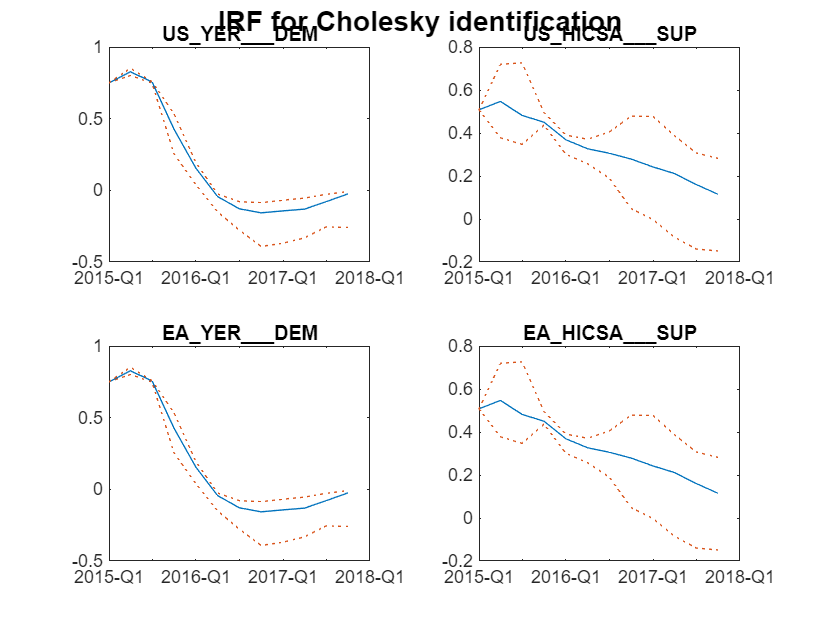




ch = visual.Chartpack( ...
  span=plotSpan, ...
  namesToPlot=["US_YER___DEM","US_HICSA___SUP","EA_YER___DEM", "EA_HICSA___SUP" ], ...
  plotSettings=plotSettings ...
);

ch.Captions = "IRF for Cholesky identification";
ch.plot(respTbl1);

## **Historical shock decomposition**


histContTbx = modelS1.calculateContributions();

tablex.getHigherDims(histContTbx)

ans = 1×1 cell array
    {["DEM"    "SUP"    "POL"    "Exogenous"    "Initials"]}


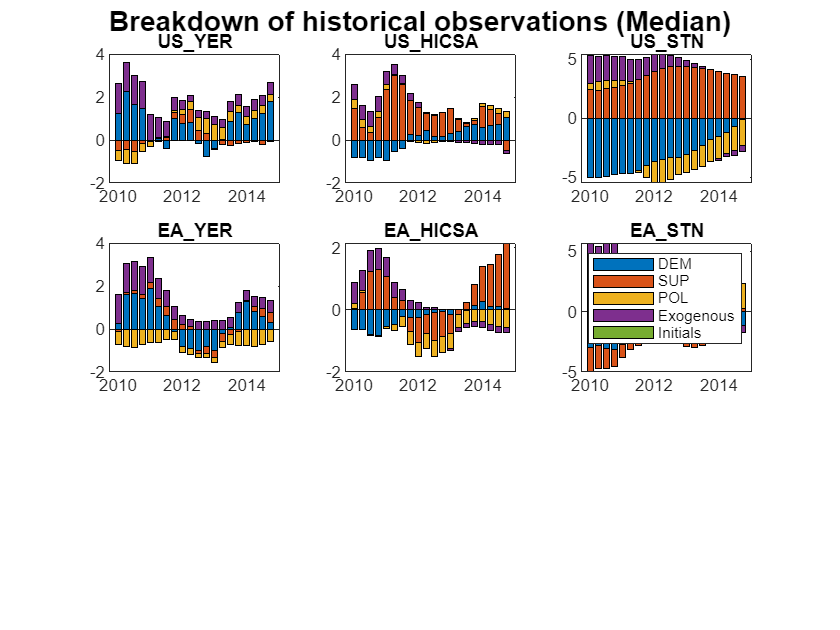


histContMedTbx = tablex.apply(histContTbx, medianFunc);
histContMedTbx = tablex.apply(histContMedTbx, flatFunc);

ch = visual.Chartpack( ...
    span=datex.span("2010-Q1", "2014-Q4"), ...
    namesToPlot=modelS1.Meta.EndogenousNames, ...
    captions="Breakdown of historical observations (Median)", ...
    plotFunc=@bar ...
);
ch.plot(histContMedTbx);
leg = tablex.getHigherDims(histContMedTbx);
legend(leg{1});

## **Unconditional forecast shock decomposition**


[uncFcastTbl1, uncFcastContribTbl1] = modelS1.forecast( ...
    fcastSpan, ...
    contributions=true ...
);

tablex.getHigherDims(uncFcastContribTbl1)

ans = 1×1 cell array
    {["DEM"    "SUP"    "POL"    "Exogenous"    "Initials"]}


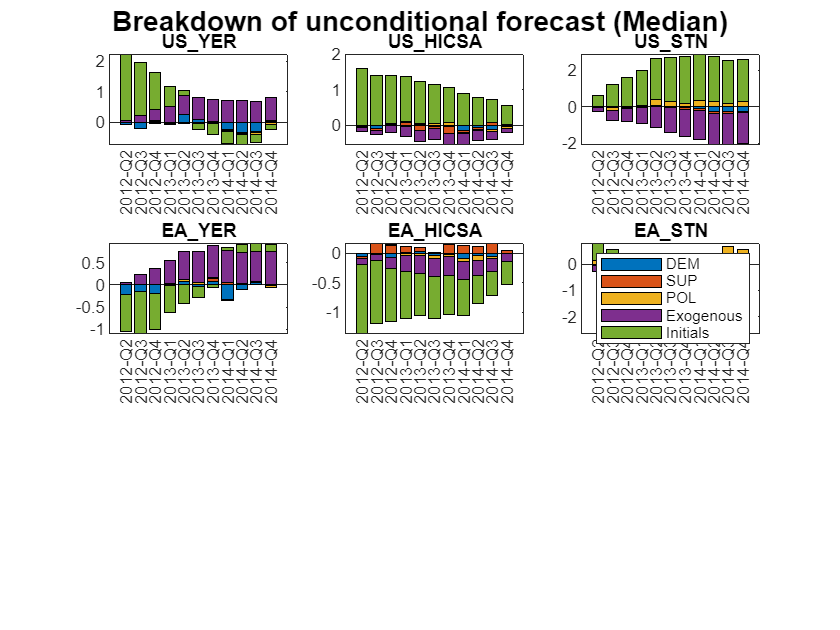


contMedTbx = tablex.apply(uncFcastContribTbl1, medianFunc);
contMedTbx = tablex.apply(contMedTbx, flatFunc);

ch = visual.Chartpack( ...
    span=fcastSpan, ...
    namesToPlot=modelS1.Meta.EndogenousNames, ...
    captions="Breakdown of unconditional forecast (Median)", ...
    plotFunc=@bar ...
);
ch.plot(contMedTbx);
leg = tablex.getHigherDims(contMedTbx);
legend(leg{1});

## **FEVD**


fevdTbx = modelS1.calculateFEVD();


  (MeanOLSPanel) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




tablex.getHigherDims(fevdTbx)

ans = 1×1 cell array
    {["DEM"    "SUP"    "POL"]}


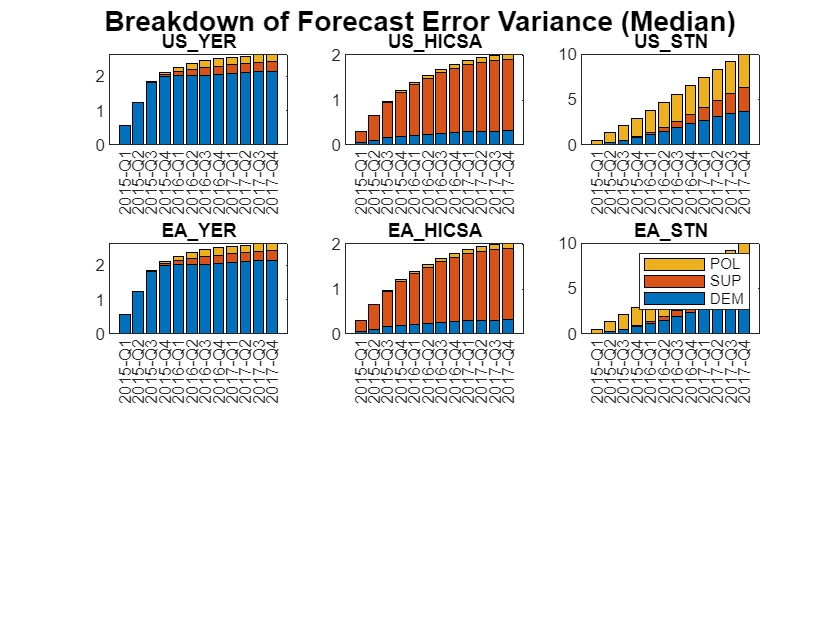


fevdMedTbx = tablex.apply(fevdTbx, medianFunc);
fevdMedTbx = tablex.apply(fevdMedTbx, flatFunc);

ch = visual.Chartpack( ...
    span=plotSpan, ...
    namesToPlot=modelS1.Meta.EndogenousNames, ...
    captions="Breakdown of Forecast Error Variance (Median)", ...
    plotFunc=@bar ...
);
ch.plot(fevdMedTbx);
leg = tablex.getHigherDims(fevdMedTbx);
legend(leg{1});

## Conditional forecast

### Settig up the conditions and the forecast plan

condDataTbl = tablex.fromFile("condDataTblPanel.xlsx");
planTbl = tablex.readConditioningPlan("planTblPanel.xlsx");

### Settig up the forecast range 

cfcastStart = datex.shift(modelR1.Meta.EstimationEnd, 1); %The forecast starts after the estimation span.
cfcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 12); 
cfcastSpan = datex.span(cfcastStart, cfcastEnd);

### Running conditional forecast with no simulation plan

[condFcastTbl1, condFcastContribTbl1] = modelS1.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=[], ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl1 = tablex.apply(condFcastTbl1, prctileFunc);

### Running conditional forecast with simulation plan

[condFcastTbl2, condFcastContribTbl2] = modelS1.conditionalForecast( ...
    cfcastSpan, ...
    conditions=condDataTbl, ...
    plan=planTbl, ...
    exogenousFrom = "conditions" ...
);


 Conditional forecast [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 




condFcastPrctilesTbl2 = tablex.apply(condFcastTbl2, prctileFunc);

### Visualize the conditional forecast

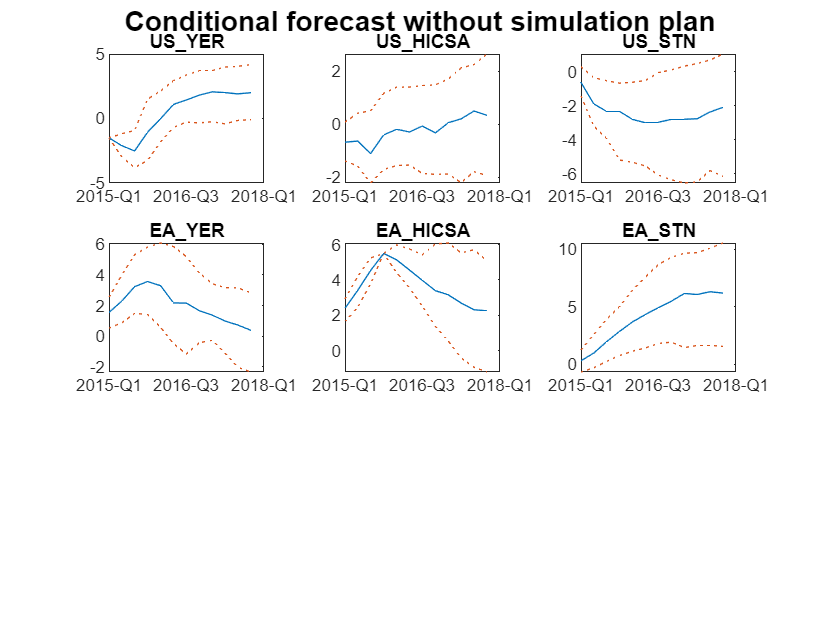

ch = visual.Chartpack( ...
  span=cfcastSpan, ...
  namesToPlot=[modelS1.Meta.EndogenousNames], ...
  plotSettings=plotSettings ...
);

ch.Captions = "Conditional forecast without simulation plan";
ch.plot(condFcastPrctilesTbl1);

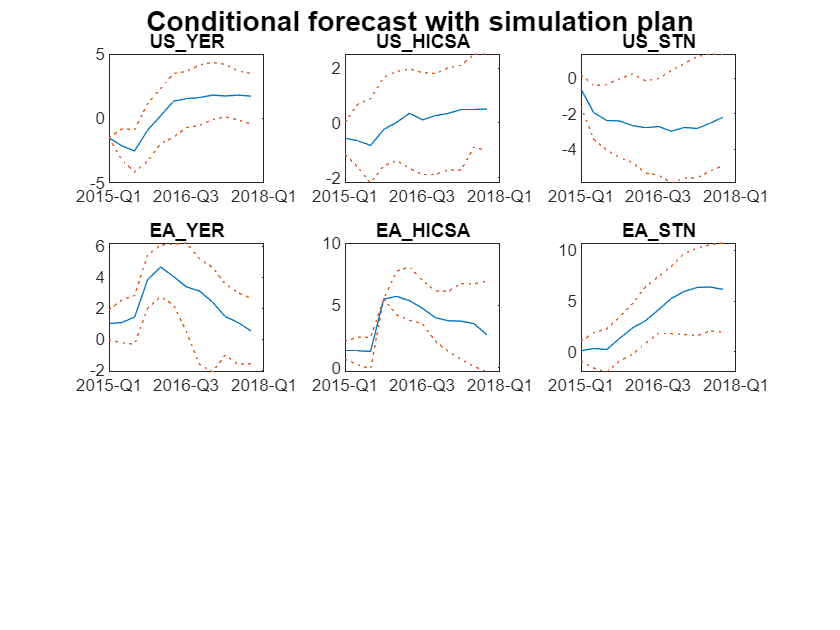


ch.Captions = "Conditional forecast with simulation plan";
ch.plot(condFcastPrctilesTbl2);